# TEST SULLA RIPETIBILITA' DEL ROBOT

La ripetibilità è una misura della capacità del dispositivo di posizionare il laser nello stesso punto quando viene comandato ripetutamente con gli stessi input. L'approccio specifico utilizzato è:

**Ripetibilità unidirezionale**:

- I punti vengono avvicinati sempre dalla stessa direzione

- Per ogni punto desiderato, il sistema esegue una serie di movimenti identici e misura la distribuzione delle posizioni raggiunte.

**Metriche utilizzate**:

- La dispersione attorno al punto medio viene calcolata come la distanza standard (2σ), che rappresenta il doppio della deviazione standard delle posizioni misurate. Questa metrica garantisce una confidenza del 95% che i punti misurati si trovino entro un determinato raggio attorno alla media

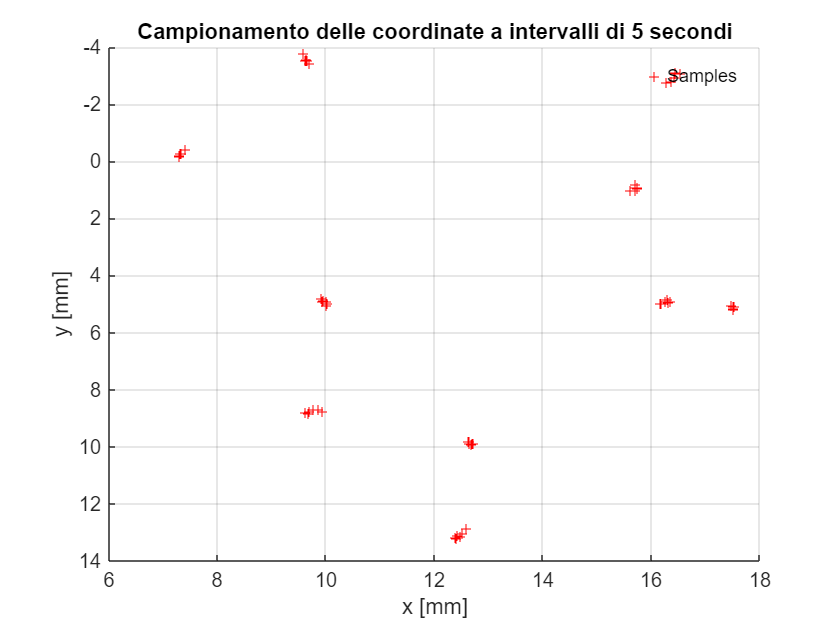

% Assumendo che coords_matrix sia una matrice N x 2
fps = video.FrameRate;  % Frame rate della telecamera (25)
interval = 5;           % Intervallo in secondi
step = fps * interval;  % Passo di campionamento 

% Campionamento delle coordinate a intervalli di 5 secondi
sampled_coords = laserWorldPoints_filtered(1:step:end, :);

% Plot delle coordinate campionate
figure
plot(sampled_coords(:,1), sampled_coords(:,2), 'r+', 'MarkerSize', 5)
legend('Samples')
title('Campionamento delle coordinate a intervalli di 5 secondi')
xlabel('x [mm]')
ylabel('y [mm]')
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
grid on
box off
legend box off

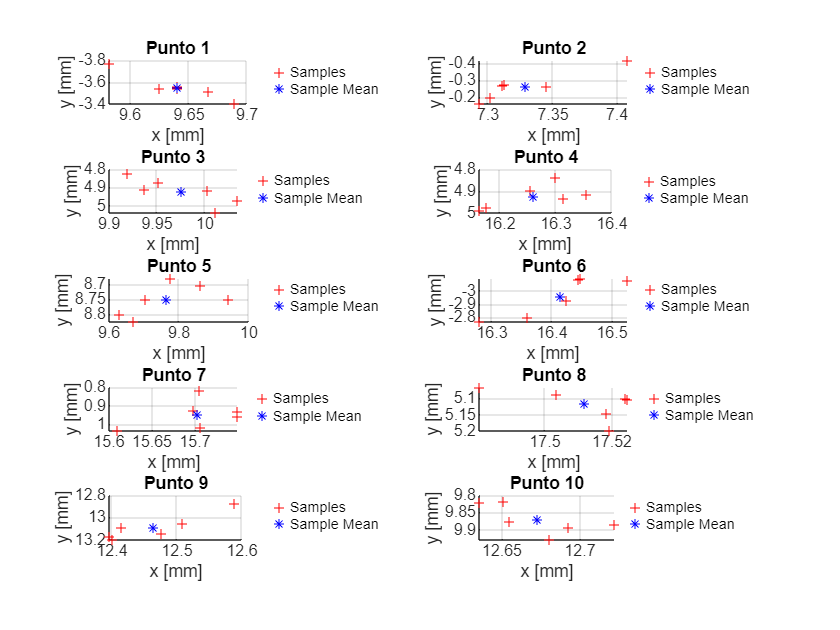

num_points = 10;
each_point = cell(1, num_points);
point_mean = cell(num_points,1);
point_std = cell(num_points,1);
dispersion = cell(num_points, 1);

figure
for i = 1:num_points
    
    % Estrai i punti del gruppo
    each_point{i} = sampled_coords(i:10:end,:);

    % % Calcola la media delle coordinate x e y
    point_mean{i} = [mean(each_point{i}(:, 1)), mean(each_point{i}(:, 2))];

    % Calcola la deviazione standard delle coordinate x e y
    point_std{i} = [std(each_point{i}(:, 1)), std(each_point{i}(:, 2))]; 
    % calcola la dispersione come raggio
    dispersion{i} = 2*sqrt(point_std{i}(1)^2 + point_std{i}(2)^2); % Distanza standard (2σ)

    subplot(ceil(num_points / 2), 2, i); % Dispone i grafici su 2 colonne
    plot(each_point{i}(:, 1), each_point{i}(:, 2), 'r+', 'MarkerSize', 5);
    hold on;
    plot(point_mean{i}(1), point_mean{i}(2), 'b*', 'MarkerSize', 5); % Punto medio
    legend('Samples', 'Sample Mean')
    legend Location bestoutside
    legend box off
    box off
    grid on
    xlabel 'x [mm]'
    ylabel 'y [mm]'
    title(['Punto ', num2str(i)]); % Titolo con numero normale
    set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo

end

% Converte dispersion in un array numerico
numeric_dispersion = cell2mat(dispersion) * 1000; % Converti in micrometri;

% Trova l'indice del massimo
[max_dispersion, idx] = max(numeric_dispersion);

% Stampa il risultato
fprintf('Punto con dispersione massima: %d\n', idx);

Punto con dispersione massima: 6


fprintf('Valore della dispersione massima: %.2f µm\n', max_dispersion);

Valore della dispersione massima: 343.52 µm


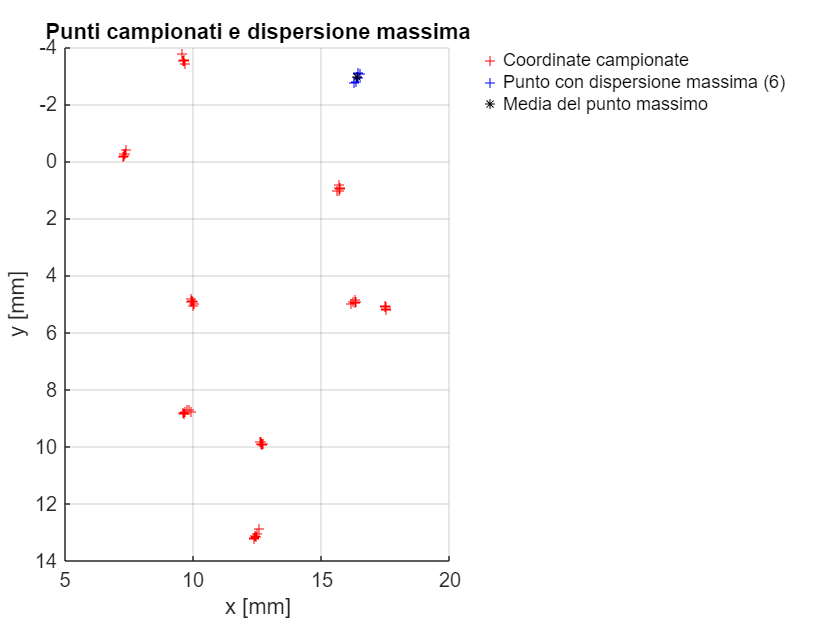

% Sovrapposizione su grafico principale
figure;
plot(sampled_coords(:,1), sampled_coords(:,2), 'r+', 'MarkerSize', 5); hold on;
plot(each_point{idx}(:,1), each_point{idx}(:,2), 'b+', 'MarkerSize',5 ); % Evidenzia in verde
plot(point_mean{idx}(1), point_mean{idx}(2), 'k*', 'MarkerSize', 5); % Media evidenziata
legend('Coordinate campionate', ['Punto con dispersione massima (', num2str(idx), ')'], ...
       'Media del punto massimo', 'Location', 'bestoutside');
legend box off
xlabel('x [mm]');
ylabel('y [mm]');
set(gca, 'YDir', 'reverse'); % Riflette il piano mondo
grid on; box off;
title('Punti campionati e dispersione massima');

% Crea una tabella con i risultati
Punto = (1:num_points)'; % Numeri dei punti
Dispersione_mm = numeric_dispersion'; % Dispersione in mm

% Crea la tabella
dispersion_table = table(Punto, Dispersione_mm', ...
                         'VariableNames', {'Punto', 'Raggio di dispersione [µm]'});

% Mostra la tabella in console
disp(dispersion_table);

    Punto    Raggio di dispersione [µm]
    _____    __________________________

      1                 244.3          
      2                195.05          
      3                177.29          
      4                188.89          
      5                264.71          
      6                343.52          
      7                184.38          
      8                101.72          
      9                278.28          
     10                107.43          



% (Opzionale) Salva la tabella in un file Excel per analisi future
writetable(dispersion_table, 'dispersion.xlsx');